%% kinematic simulation two-wheeled mobile robot
clear all 
clc
close all 


%% simulation parameter

total_time = 10;  % (seconds)
dt = 0.1; % step sizes
time_stamp = total_time/dt; % simulation time
i = 1; % to start while loop


%% mobile robot parameter and initial contitions
theta_i = 0; % initial orientation
v_i = 1; % linear velocity
w_i = 1; % angular velocity
x_pos = zeros(3, time_stamp); % to store position values
point = [0;0;0]; % ititial position and orientation


%% loop starts here
while i <= time_stamp
    x_pos(1:2,i) = point(1:2);
    x_pos(3,i) = theta_i;
    time(i) = i/10;
    q_dot = model(theta_i,v_i,w_i); % time derivative of position
    point(1:2) = point(1:2) + q_dot(1:2) * dt; % state (position) update
    theta_i = theta_i + q_dot(3) * dt; % state (orientation) update
    i = i + 1;
end 

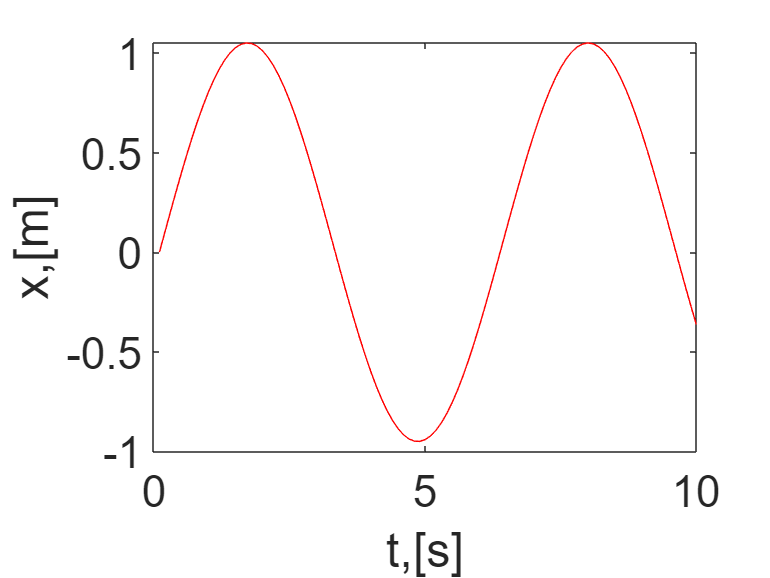


% plotting functions
figure
plot(time, x_pos(1,:),'r');
set(gca, 'fontsize',24)
xlabel('t,[s]');
ylabel('x,[m]');

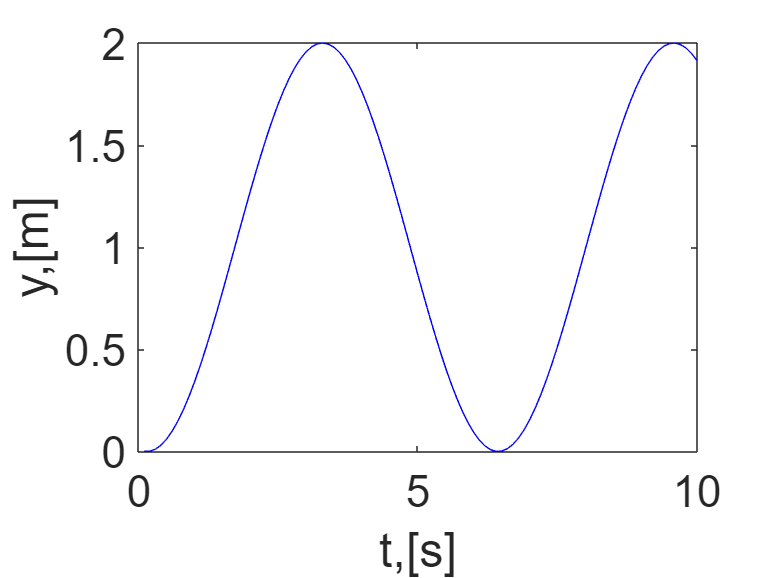


%
figure
plot(time, x_pos(2,:),'b-');
set(gca,'fontsize',24);
xlabel('t,[s]');
ylabel('y,[m]');

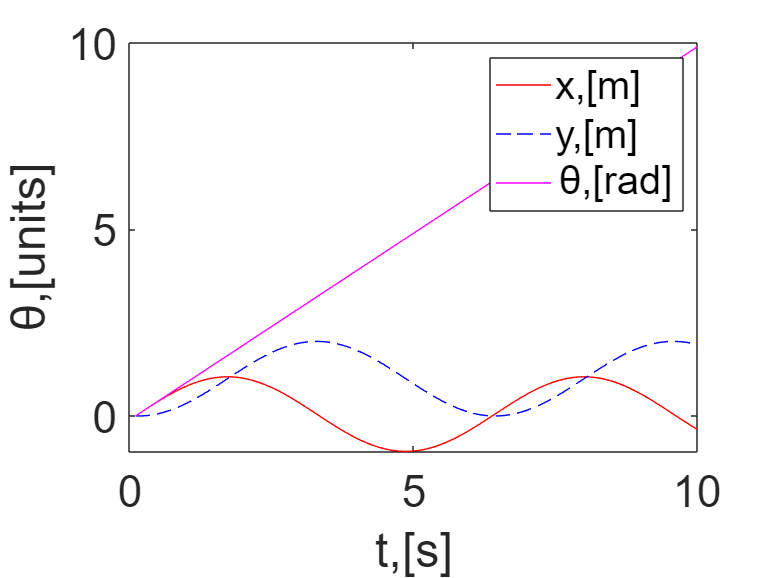


figure
plot(time, x_pos(1,:),'r');
hold on
plot(time, x_pos(2,:),'b--');
plot(time, x_pos(3,:),'m');
legend('x,[m]','y,[m]','\theta,[rad]');
set(gca,'fontsize',24)
xlabel('t,[s]');
ylabel('\theta,[units]');

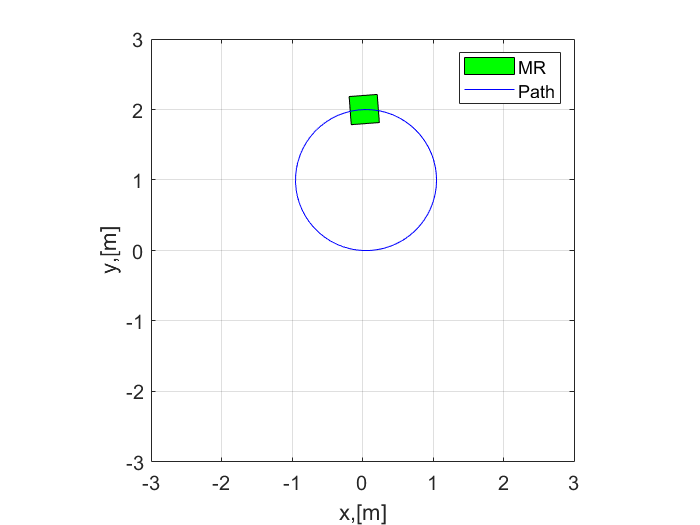


%% Animation (mobile robot motion animation)
l = 0.4; % length of the mobile robot
w = 0.4; % width of the mobile robot
% Mobile robot cooridinates
box_v = [-l/2,l/2,l/2,-l/2,-l/2;
         -w/2,-w/2,w/2,w/2,-w/2;];   
figure
for i = 1:5:length(time)
    theta = x_pos(3,i);
    R_theta = [cos(theta), -sin(theta);
             sin(theta), cos(theta);]; % rotation matrix
    v_pos = R_theta*box_v;
    fill(v_pos(1, :)+x_pos(1,i),v_pos(2,:)+x_pos(2,i),'g')
    hold on, grid on
    axis([-3 3 -3 3]), axis square
    plot(x_pos(1,1:i),x_pos(2,1:i),'b-');
    legend('MR','Path')
    set(gca, 'fontsize',12)
    xlabel('x,[m]'); ylabel('y,[m]');
    pause(1)
    hold off
end % animation ends here